Triangular window function with respect to M=10


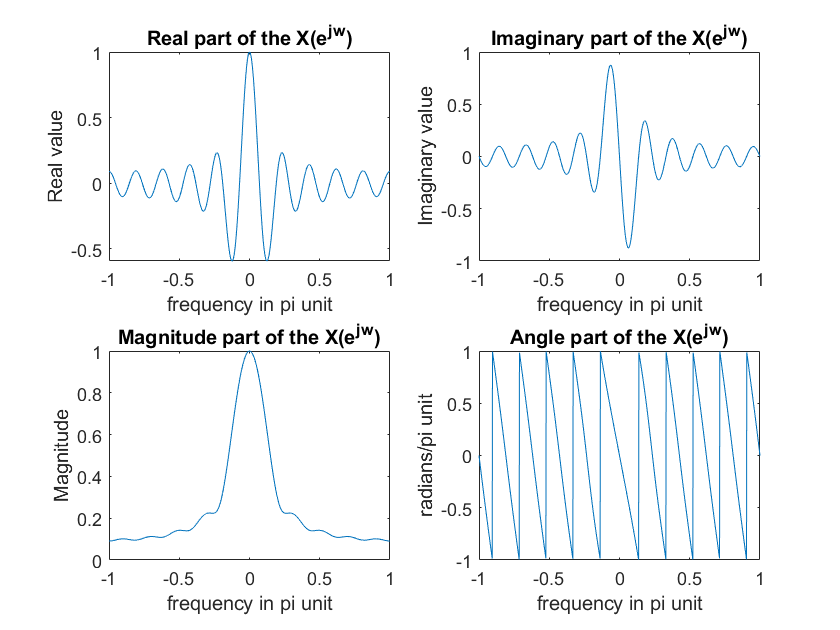

Triangular window function with respect to M=25


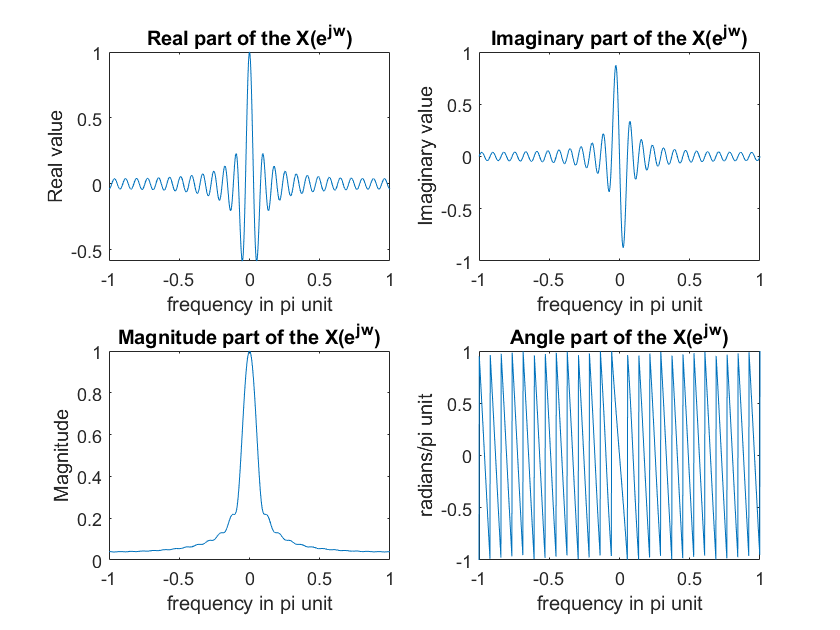

Triangular window function with respect to M=50


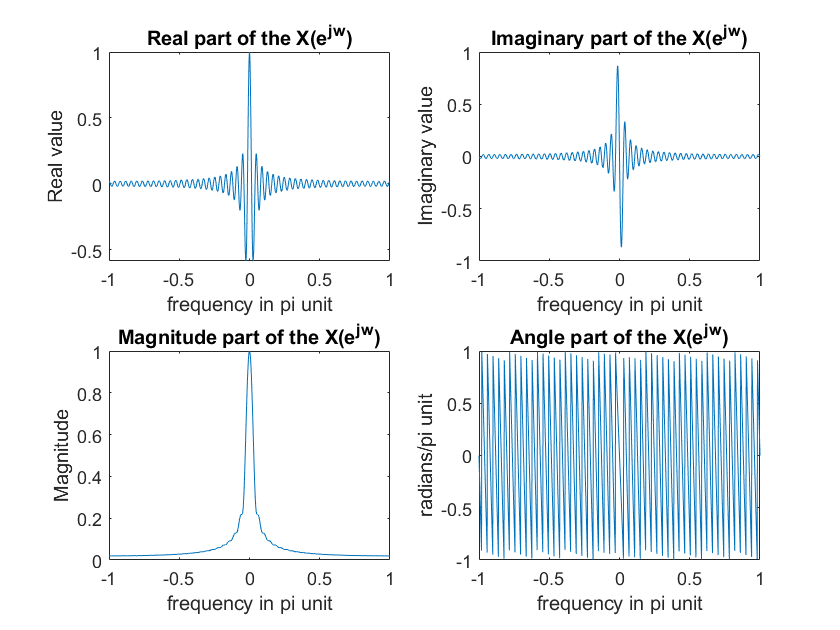

Triangular window function with respect to M=101


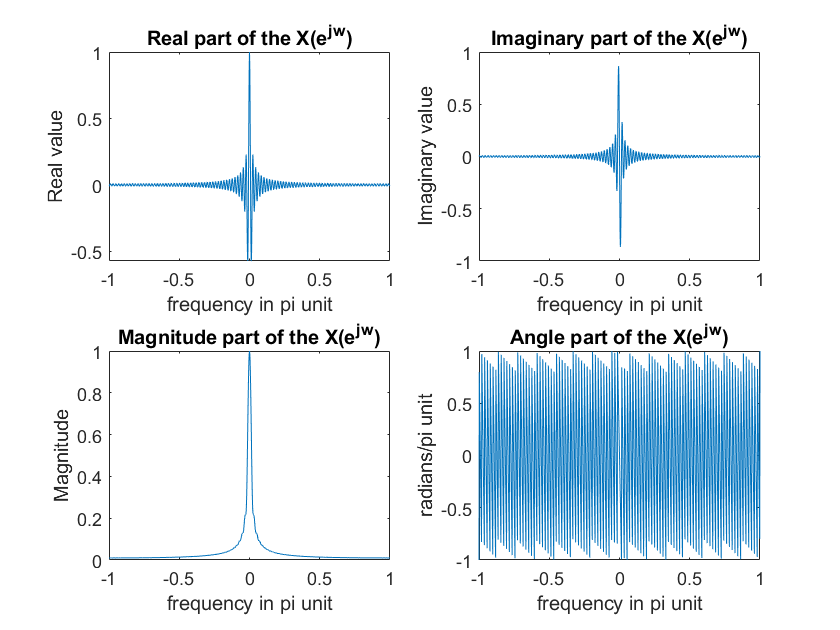

% Triangular Window
K=500;
k=-K:K;
w=(pi*k)/K;
M=[10 25 50 101];
for i=1:length(M)
    figure('Name',strcat('M=',num2str(M(i))))
    n=-50:M(i);
    tri=unitseq(min(n),M(i),0).*(1-(M(i)-1-2*n)/(M(i)-1));
    X=dtft(tri,n,K);
    disp(strcat('Triangular window function with respect to M=',num2str(M(i))))
    dfp4(X/max(X),w)    
end